# **PRÀCTICA G9: Processament d'imatges a color **

**Número de Grup:**

**Nom:**

Pràctica dissenyada per aplicar els conceptes de tècniques de processament d'imatges a color, com Sharpening i Segmentation explicat a classe.

## **Ex1: Correccions de to i color.**

Aplicar les seguents correcions de to i colors a tota la imatge original:

- Sobreexposició (correció de to)

- Subexposició (correcció de to)

- Augmentar saturació (correcció de color)

- Reduir saturació (correcció de color)

imagen = imread('peppers.png');

% Completar el codi
imagen_sobreexpuesta = 
imagen_subexpuesta = 
imagen_saturada = 
imagen_desaturada = 

% Mostrar les imatges
subplot(2, 3, 1);
imshow(imagen);

Invalid expression. Check for missing or extra characters.

title('Imatge original');

subplot(2, 3, 2);
imshow(imagen_sobreexpuesta);
title('Imatge sobreexposada');

subplot(2, 3, 3);
imshow(imagen_subexpuesta);
title('Imatge subexposada');

subplot(2, 3, 4);
imshow(imagen_saturada);
title('Imatge saturada');

subplot(2, 3, 5);
imshow(imagen_desaturada);
title('Imatge desaturada');

## **Ex2: Sharpening Filter utilitzant Laplacian.**

Resalta els colors de la imatge "flores.jpg", és a dir, fes-la més nitida, per tal de que s'observin els detalls:

NOTA: Podeu anar observant com va canviant la imatge amb diferents kernels.

img = imread('flores.jpg');
img = im2double(img);

imatge_laplaciana = 

% Mostrar la imatge original y la imatge millorada
figure;
imshowpair(img, imagen_laplaciana, 'montage');

## Ex3: Edge filtering

Aplica l'algorisme de Edge Filtering, per tal de resaltar els colors on hi ha un canvi brusc a la imatge "flores.jpg". 


edgeImage = 

figure;
imshowpair(img, edgeImage, 'montage');

## Ex4: Image Segmentation

Utilitza el "Graph Cut" de l'eina "Image Segmenter" de MatLab  per a separar el fons de l'element principal. Un cop exportada la màscara, executa el següent codi per a crear la visualització la retallada.

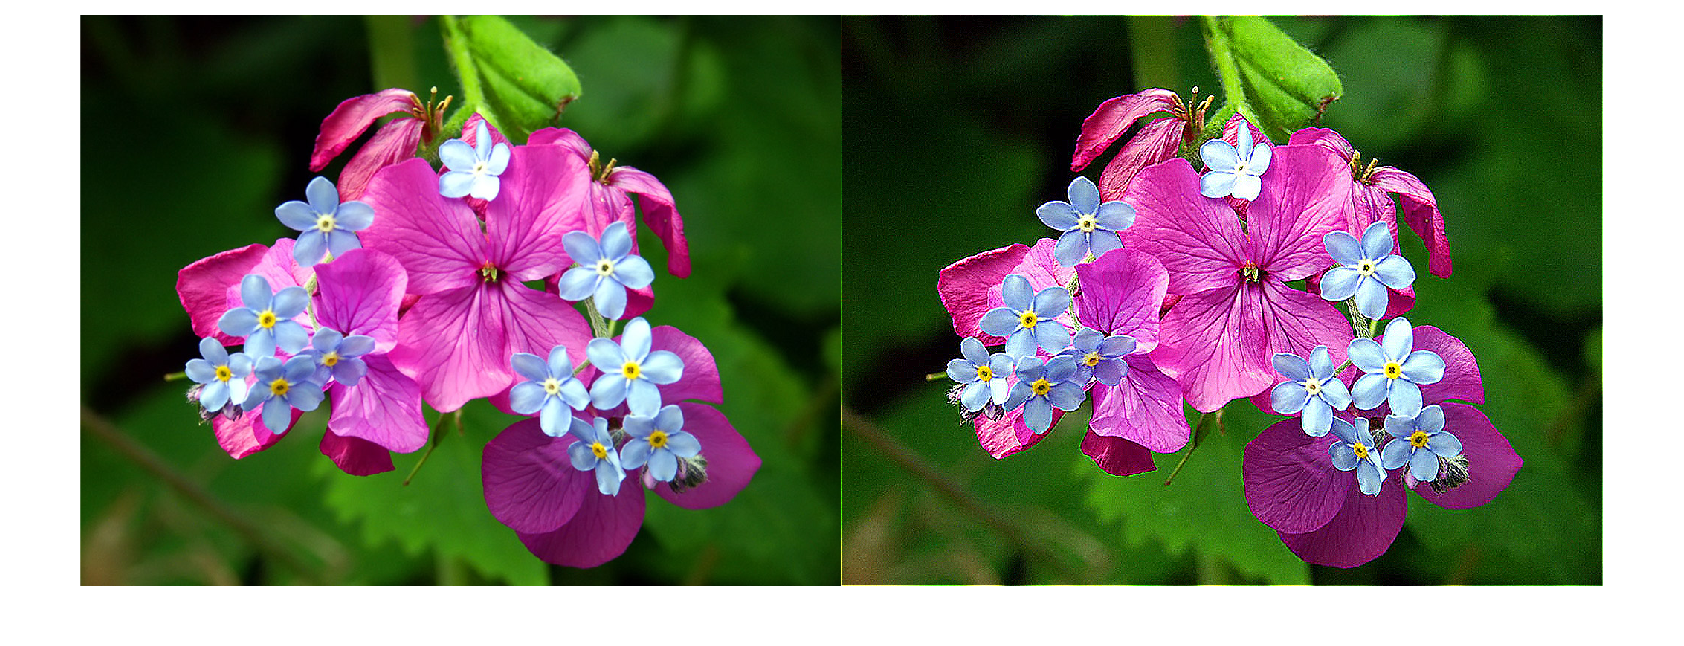

rgbImage = imread("imatge_exemple.jpg"); % Podeu utilitzar una imatge qualsevol, mentre es pugui distingir un o diversos elements del fons
mask = ; % Variable resultant d'exportar la màscara amb la eina "Image Segmenter al workspace"


fontSize = 14;

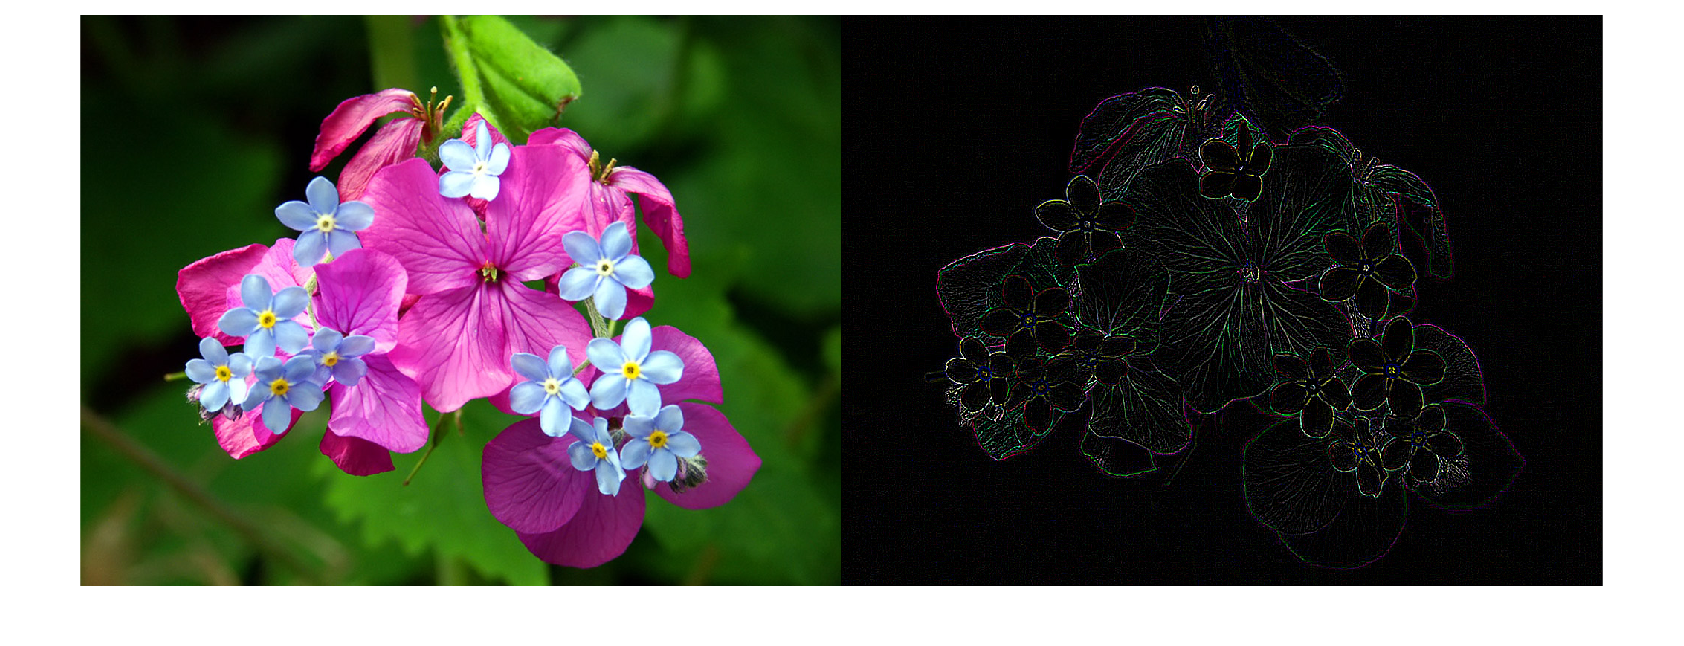

subplot(2, 2, 1);
imshow(rgbImage, []);
caption = sprintf('Imatge');
title(caption, 'FontSize', fontSize, 'Interpreter', 'None');

subplot(2, 2, 2);
imshow(mask, []);

title('Mask', 'FontSize', fontSize, 'Interpreter', 'None');

maskedRgbImage = bsxfun(@times, rgbImage, cast(mask, 'like', rgbImage));
subplot(2, 2, 3);
imshow(maskedRgbImage, []);
title('Masked Image', 'FontSize', fontSize, 'Interpreter', 'None');

backgroundImage = bsxfun(@times, rgbImage, cast(~mask, 'like', rgbImage));
subplot(2, 2, 4);
imshow(backgroundImage, []);
title('Background Image', 'FontSize', fontSize, 'Interpreter', 'None');